## $k$-Means Clustering

An important method for data compression and classification is to organize data points into clusters. The algorithm is as follows. Assume we have $n$ data points $(a_{ij})_{j=1}^n \in \mathbb{R}^m$ which are organized in a matrix as columns $A \in \mathbb{R}^{n \times m}.
$ Let $\prod = (\pi_i)_{j=1}^k$ denote a partitioning of the vectors $a_1, \dots, a_n$ into $k$ clusters: $\pi_j = \left \{ v | a_v \text{ belongs in cluster } j \right \}$. The mean (or centroid) of the cluster be:

    
$$
m_{j}=\frac{1}{n_{j}}\underset{\nu\in\pi_{j}}{\sum}a_{\nu},$$


Where $n_j$ is the number of elements in $\pi_j$. We define clusters based on a distance measure. In this case, we choose Euclidean distance. The coeherence (or tightness) of the cluster can be measured as the sum:

    
$$q_{j}=\underset{\nu\in\pi_{j}}{\sum}\left\Vert a_{\nu}-m_{j}\right\Vert
_{2}^{2}.$$


The closer the vectors are to the centriod, the smaller the value of $q_j$. Thus, the overall coherence (a notion of quality) of the clustering algorithm can be measured:

     
$$Q\left(  \Pi\right)  =\underset{j=1}{\overset{k}{\sum}}q_{j}%
=\underset{j=1}{\overset{k}{\sum}}\underset{\nu\in\pi_{j}}{\sum}\left\Vert
a_{\nu}-m_{j}\right\Vert _{2}^{2}.$$


In the $k$−Means algorithm, we seek a partitioning that has optimal coherence, in the sense that it is thesolution of the minimization problem

    
$$\underset{\Pi}{\min}Q\left(  \Pi\right)$$


**The basic idea of the algorithm is straightforward.  Given a partitioning, one computes the centroids.  Then, for each data point in a particular cluster, one checks whether there is another centroid that closer than the present cluster centroid.  If that is the case, then a redistribution is made. The initial partitioning is often chosen  randomly.  The algorithm usually has fast convergence, but one cannot guarantee  that the algorithm finds the global minimum.**

### The Algorithm:

- Start with an initial partitioning $\prod^0$ and compute the centriods, $\left ( m_j^{(0)} \right )_{j=1}^k$. Compute $Q(\prod^0)$. Put $t=1$. 

- For each vector $a_i$, find the closest centriod (using the distance measure). If the closest vector is $m_p^{(t-1)}$, assign $a_i$ to $\pi_p^{(t)}$. 

- Compute the centriods $\left ( m_j^{(t)} \right )_{j=1}^k$ of the new partioning $\prod^t$. 

- If $|Q(\prod^{t-1} ) -  Q(\prod^{t} )  | < tol$, then stop; otherwise increment $t$ by 1 and repeat (from step 2).

### An Example:

In this section we train a $k$-Means Clustering Algorithm on the [Fisher's iris data set](https://en.wikipedia.org/wiki/Iris_flower_data_set). This example comes from the [MATLAB kmeans documentation](https://www.mathworks.com/help/stats/kmeans.html). We use the petal lengths and widths as predictors. The data, which is available directly from MATLAB:

load fisheriris
X = meas(:,3:4);
size(X)

ans =    150     2


Make an initial scatterplot of the data:

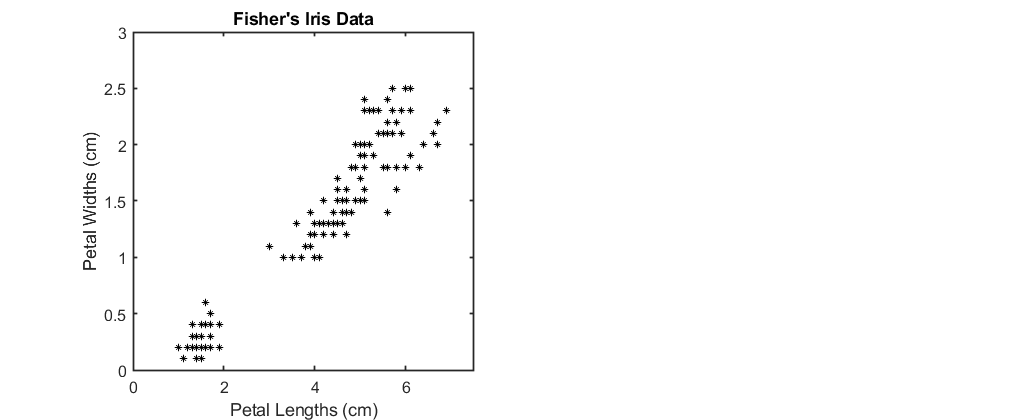

figure('Position', [448 442 1020 420]);
subplot(1,2,1);
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title('Fisher''s Iris Data');
xlabel('Petal Lengths (cm)'); 
ylabel('Petal Widths (cm)');
set(gca,'FontSize',12,'LineWidth',1.25,'YLim',[0, 3],'XLim',[0, 7.5],'Layer','Top')

We must specify the number of clusters. Here I choose $k = 3$ clusters based on the plot above. To me, it looks like there are three "groups" of flowers. We can use the `kmeans()` function to get the cluster "ids" and the cluster centriods from the data. Note that the variable `clusters` has the same number of rows as the original data. Each row has an integer value that is the "cluster id" for that flower. A value of 2 means: "this flower is in cluster number 2."

k = 3; % feel free to change this number!
[clusters, cluster_centers] = kmeans(X,3)

clusters =      2
     2
     2
     2
     2
     2
     2
     2
     2
     2


cluster_centers =     5.5958    2.0375
    1.4620    0.2460
    4.2692    1.3423


We can make a simple plot with each data-point (flower) colored according to its cluster id.

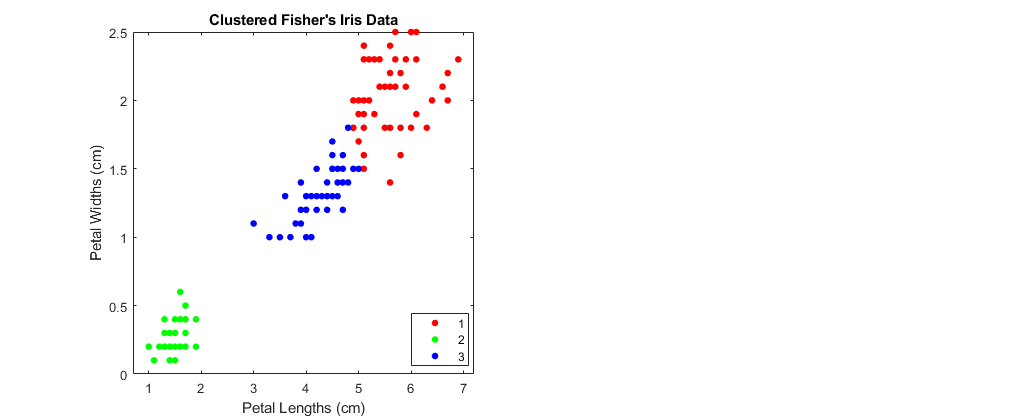

gscatter(X(:,1),X(:,2), clusters)
title('Clustered Fisher''s Iris Data');
xlabel('Petal Lengths (cm)'); 
ylabel('Petal Widths (cm)');

We can also visualize the result of the clustering by showing the regions in 2D space that grouped together. 

x1 = 0:0.01:max(X(:,1))+.6;
x2 = 0:0.01:max(X(:,2))+.5;
[x1G,x2G] = meshgrid(x1,x2);
XGrid = [x1G(:),x2G(:)]; % Defines a fine grid on the plot

idx2Region = kmeans(XGrid,k,'MaxIter',1,'Start',cluster_centers);    % Assigns each node in the grid to the closest centroid

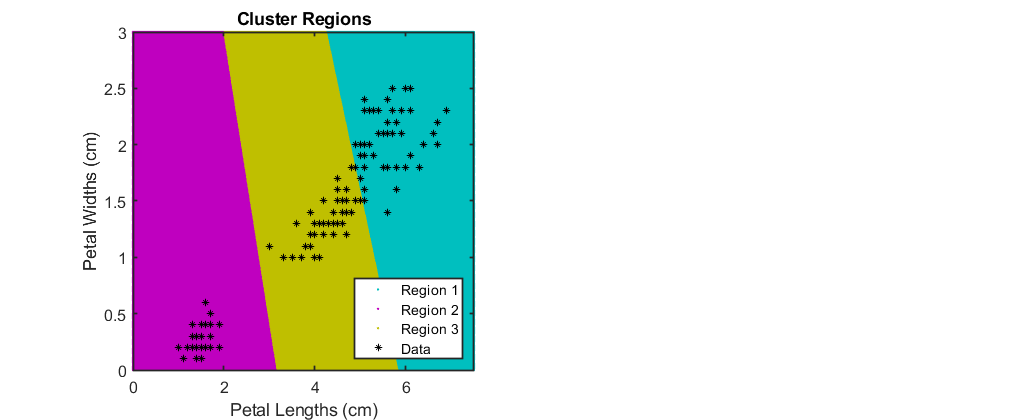

gscatter(XGrid(:,1),XGrid(:,2),idx2Region,...
    [0,0.75,0.75;0.75,0,0.75;0.75,0.75,0],'..');
hold on;
plot(X(:,1),X(:,2),'k*','MarkerSize',5);
title 'Cluster Regions';
xlabel 'Petal Lengths (cm)';
ylabel 'Petal Widths (cm)'; 
legend('Region 1','Region 2','Region 3','Data','Location','SouthEast');
set(gca,'FontSize',12,'LineWidth',1.25,'YLim',[0, 3],'XLim',[0, 7.5],'Layer','Top')
hold off;

### An Example on Random Data

This code block shows how to plot clustering results on random data. 

X = [randn(100,2)*0.75+ones(100,2);
    randn(100,2)*0.5-ones(100,2)];

Plot it, for our sanity.

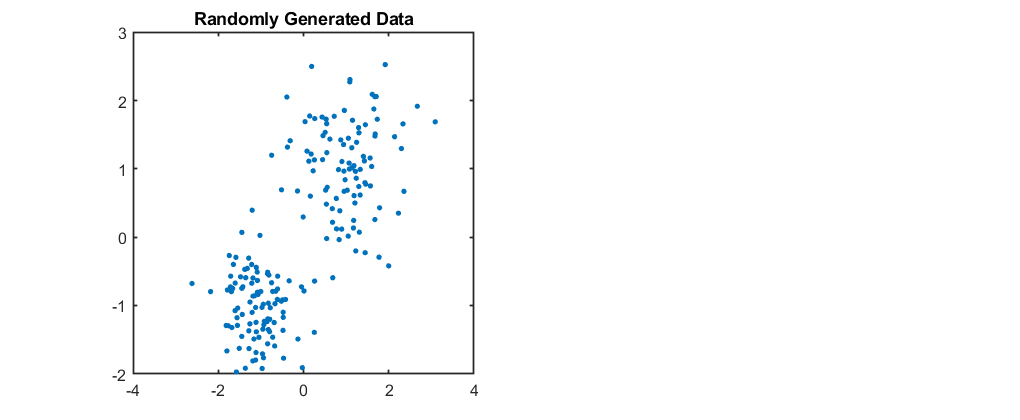

figure('Position', [448 442 1020 420]);
subplot(1,2,1)
plot(X(:,1),X(:,2),'.','MarkerSize',12);
title 'Randomly Generated Data';
axis square
set(gca,'FontSize',12,'LineWidth',1.25)

Finally we plot the clustering results and the centriods of each cluster.

opts = statset('Display','final');
[idx,C] = kmeans(X,2,'Distance','cityblock',...
    'Replicates',5,'Options',opts);

Replicate 1, 3 iterations, total sum of distances = 186.769.
Replicate 2, 2 iterations, total sum of distances = 186.769.
Replicate 3, 2 iterations, total sum of distances = 186.769.
Replicate 4, 1 iterations, total sum of distances = 186.769.
Replicate 5, 2 iterations, total sum of distances = 186.769.
Best total sum of distances = 186.769


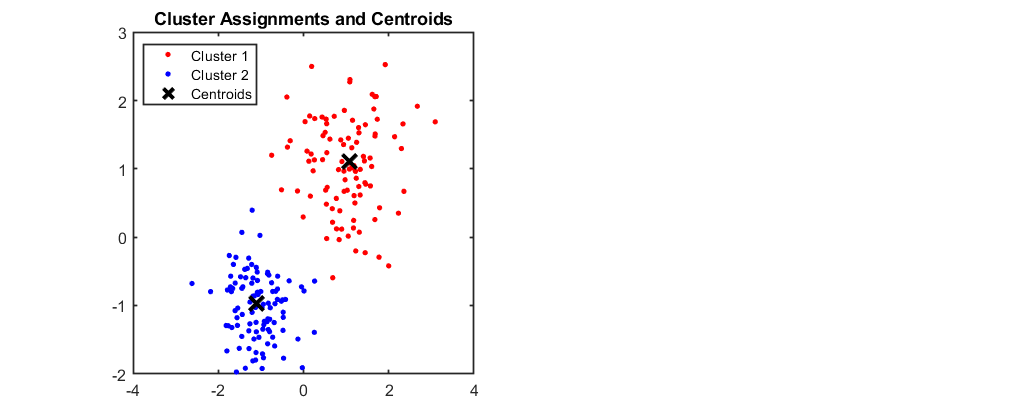


plot(X(idx==1,1),X(idx==1,2),'r.','MarkerSize',12)
hold on
plot(X(idx==2,1),X(idx==2,2),'b.','MarkerSize',12)
plot(C(:,1),C(:,2),'kx',...
     'MarkerSize',15,'LineWidth',3) 
legend('Cluster 1','Cluster 2','Centroids',...
       'Location','NW')
title 'Cluster Assignments and Centroids'
hold off
axis square
set(gca,'FontSize',12,'LineWidth',1.25)